% Author: Christopher Bourjaili
% Module 2
% Project 1
% Title: Vehicle Braking Distance Simulator
%
% Summary of Code:
% - Simulates vehicle stopping motion under braking force.
% - Uses time-stepped logic to calculate speed and distance.
% - Compares stopping distances for multiple initial speeds.
% - Determines how long each vehicle takes to stop.
% - Creates a stopping distance plot for comparison.
% - Demonstrates safety effects of higher travel speeds.
%
% What I Learned:
% This project demonstrated how MATLAB can simulate vehicle motion using
% physics principles, loops, and numerical time-stepping methods. I learned
% that vehicles traveling at higher initial speeds require much longer
% stopping distances, even with the same braking force. This highlights
% the importance of safe speeds, reaction space, and braking performance
% in automotive safety design.

clc
clear
close all

mass = 1500;                 
brake_force = 6000;          
dt = 0.1;                    
t_max = 30;                  

v0 = [10 20 30];

colors = ['r','g','b'];

figure
hold on
grid on

for j = 1:length(v0)
    
    t = 0:dt:t_max;
    n = length(t);
    
    velocity = zeros(1,n);
    distance = zeros(1,n);
    
    velocity(1) = v0(j);
    
    for i = 2:n
        
        accel = -brake_force / mass;
        
        velocity(i) = velocity(i-1) + accel*dt;
        
        if velocity(i) < 0
            velocity(i) = 0;
        end

        distance(i) = distance(i-1) + velocity(i-1)*dt;

        if velocity(i) == 0
            stop_time = t(i);
            stop_distance = distance(i);
            break
        end
    end
 
    plot(t(1:i), distance(1:i), colors(j), 'LineWidth',2)

    fprintf('Initial Speed = %.1f m/s\n', v0(j));
    fprintf('Stopping Time = %.2f s\n', stop_time);
    fprintf('Stopping Distance = %.2f m\n\n', stop_distance);
    
end

Initial Speed = 10.0 m/s


Stopping Time = 2.50 s


Stopping Distance = 13.00 m



Initial Speed = 20.0 m/s


Stopping Time = 5.10 s


Stopping Distance = 51.00 m



Initial Speed = 30.0 m/s


Stopping Time = 7.60 s


Stopping Distance = 114.00 m



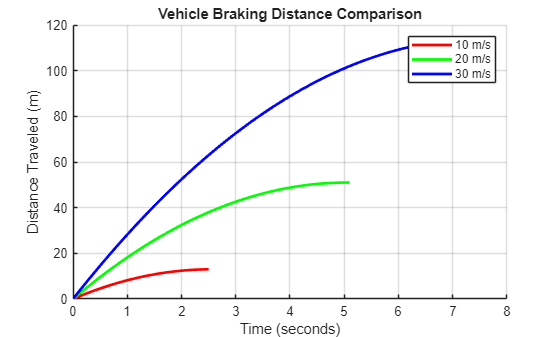


xlabel('Time (seconds)')
ylabel('Distance Traveled (m)')
title('Vehicle Braking Distance Comparison')
legend('10 m/s','20 m/s','30 m/s')


disp('Safety Interpretation:')

Safety Interpretation:


disp('1. Higher starting speeds require greater stopping distance.')

1. Higher starting speeds require greater stopping distance.


disp('2. Equal braking force cannot stop faster vehicles as quickly.')

2. Equal braking force cannot stop faster vehicles as quickly.


disp('3. Speed control is critical for collision prevention.')

3. Speed control is critical for collision prevention.


disp('4. Small increases in speed can greatly increase stopping risk.')

4. Small increases in speed can greatly increase stopping risk.
